## Part 1: Acquiring the images

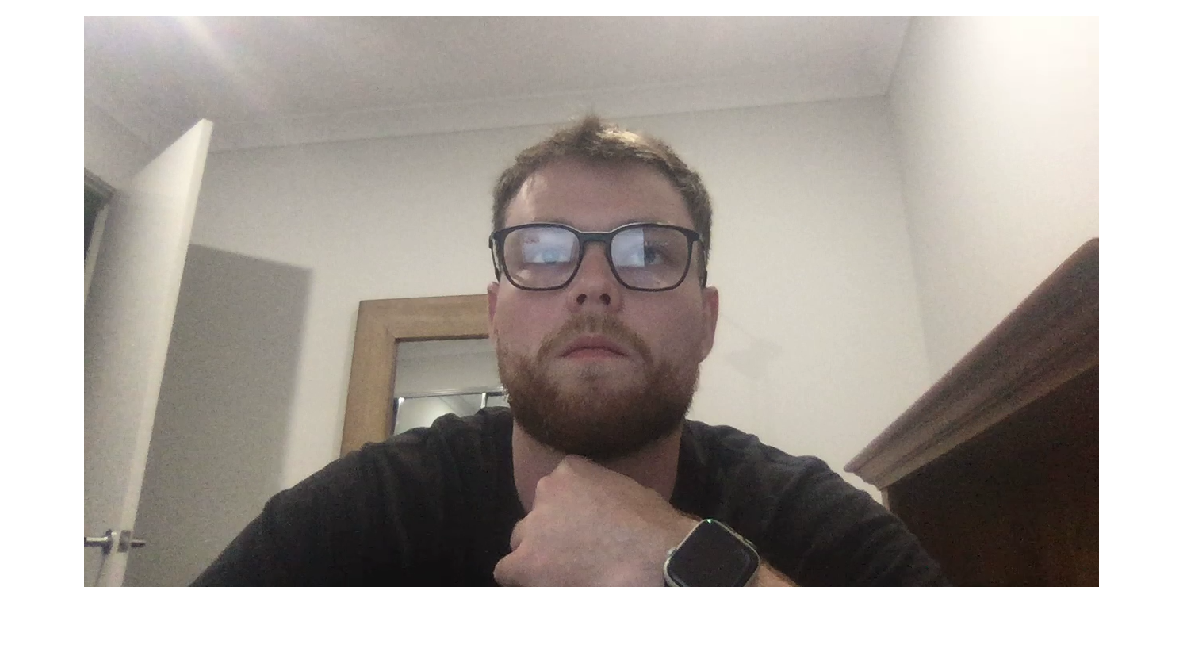

% Set camera resolution


% Create a webcam object
cam = webcam();
cam.Resolution = "224x224"

% Create output directory
output_dir = 'not_wearing_glasses';

if ~exist(output_dir, 'dir')
    mkdir(output_dir);
end

% Capture images
for i = 1:30
    % Grab snapshot
    img = snapshot(cam);

    % Show snapshot
    imshow(img);
    drawnow;

    % Create filename
    if i < 10
        filename = sprintf('00%d.jpg', i);
    elseif i < 100
        filename = sprintf('0%d.jpg', i);
    else
        filename = sprintf('%d.jpg', i);
    end

    % Write image to output directory
    imwrite(img, fullfile(output_dir, filename));
end


% Release camera
clear cam;


## Part 2: Retraining the network

% Load the pre-trained GoogLeNet model
net = googlenet;

% Modify the last layer of the network for 3 classes
numClasses = 3;
lgraph = layerGraph(net);
lgraph = removeLayers(lgraph, {'loss3-classifier','prob','output'});
newLayers = [
    fullyConnectedLayer(numClasses,'Name','fc','WeightLearnRateFactor',10,'BiasLearnRateFactor',10)
    softmaxLayer('Name','softmax')
    classificationLayer('Name','classoutput')];
lgraph = addLayers(lgraph, newLayers);
lgraph = connectLayers(lgraph,'pool5-drop_7x7_s1','fc');

% Load and preprocess the images for training
% Load and preprocess the images for training
imgSize = [224 224];
imds = imageDatastore('.', ...
                      'IncludeSubfolders', true, ...
                      'LabelSource', 'foldernames');
imds.ReadFcn = @(filename) imresize(imread(filename), imgSize);
augimds = augmentedImageDatastore(imgSize,imds);

% Split the data into training and validation sets
[trainimds,valimds] = splitEachLabel(imds,0.7,'randomized');

% Set the training options for the network
options = trainingOptions('sgdm',...
    'MiniBatchSize',16,...
    'MaxEpochs',10,...
    'InitialLearnRate',1e-4,...
    'ValidationData',valimds,...
    'ValidationFrequency',10,...
    'Verbose',false,...
    'Plots','training-progress');

% Train the network
net = trainNetwork(augimds,lgraph,options);

save("glassesTrainedNetwork.mat", 'net');

% Evaluate the performance of the trained network
[YPred,probs] = classify(net,augimds);
accuracy = mean(YPred == imds.Labels);

## Q3: Deploying and Testing the model

loadNet = load("glassesTrainedNetwork.mat")

loadNet = struct with fields:
    net: [1×1 DAGNetwork]


net = loadNet.net;


% Create a webcam object
cam = webcam();


img = snapshot(cam);
img = imresize(img, [224 224]);

label = classify(net, img);

clear cam;

disp(label);

     wearing_sunglasses 

